pos_mm_1 = t_3x3.Position_mm;
load_N_1 = t_3x3.Load_N;

pos_mm_2 = t_5x5.Position_mm;
load_N_2 = t_5x5.Load_N;

pos_mm_3 = t_5x10.Position_mm;
load_N_3 = t_5x10.Load_N;

pos_mm_4 = t_10x5.Position_mm;
load_N_4 = t_10x5.Load_N;

pos_mm_5 = t_10x10.Position_mm;
load_N_5 = t_10x10.Load_N;


Extract ROI

%%%%%   MODEL 1 - 3x3

pos_mm= pos_mm_1;
load_N= load_N_1;
plot(pos_mm,load_N)
start = 890 % start 

start = 890

stop = 2066 % stop

stop = 2066

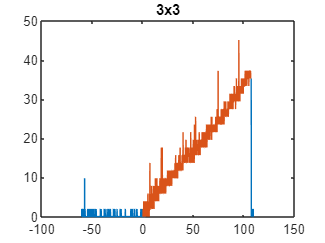

pos_mm= pos_mm(start:stop);
load_N = load_N(start:stop);
hold on
plot(pos_mm,load_N)
hold off
title("3x3")

pos_mm_1 = pos_mm;
load_N_1 = load_N;

%%%%%   MODEL 2 - 5x5
pos_mm= pos_mm_2;
load_N= load_N_2;
plot(pos_mm,load_N)
start = 2420+171 % start 

start = 2591

stop = 4005 % stop

stop = 4005

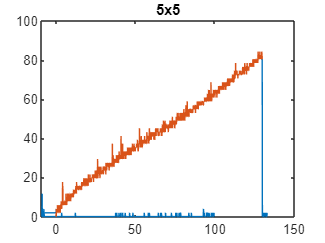

pos_mm= pos_mm(start:stop);
load_N = load_N(start:stop);
hold on
plot(pos_mm,load_N)
hold off

title('5x5')

pos_mm_2 = pos_mm;
load_N_2 = load_N;


%%%%%   MODEL 3 - 5x10

pos_mm= pos_mm_3;
load_N= load_N_3;
plot(pos_mm,load_N)
start = 2888 % start 

start = 2888

stop = 3536 % stop

stop = 3536

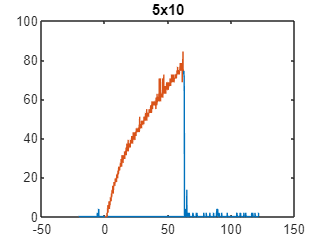

pos_mm= pos_mm(start:stop);
load_N = load_N(start:stop);
hold on
plot(pos_mm,load_N)
hold off

title('5x10')

pos_mm_3 = pos_mm;
load_N_3 = load_N;



%%%%%   MODEL 4 - 10x5
pos_mm= pos_mm_4;
load_N= load_N_4;
plot(pos_mm,load_N)
start = 2202 % start 

start = 2202

stop = 3484 % stop

stop = 3484

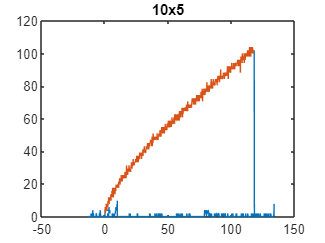

pos_mm= pos_mm(start:stop);
load_N = load_N(start:stop);
hold on
plot(pos_mm,load_N)
hold off

title('10x5')

pos_mm_4 = pos_mm;
load_N_4 = load_N;

%%%%%   MODEL 5 - 10x10
pos_mm= pos_mm_5;
load_N= load_N_5;
plot(pos_mm,load_N)
start = 3017 % start 

start = 3017

stop = 3647 % stop

stop = 3647

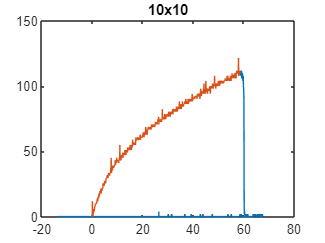

pos_mm= pos_mm(start:stop);
load_N = load_N(start:stop);
hold on
plot(pos_mm,load_N)
hold off

title('10x10')

pos_mm_5 = pos_mm;
load_N_5 = load_N;

Plot in same graf

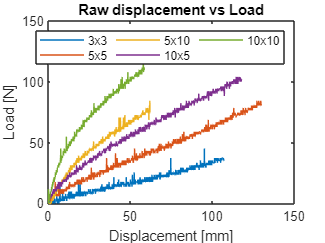


plot(pos_mm_1,load_N_1)
hold on

plot(pos_mm_2,load_N_2)
plot(pos_mm_3,load_N_3)
plot(pos_mm_4,load_N_4)
plot(pos_mm_5,load_N_5)
hold off

legend({'3x3','5x5','5x10','10x5','10x10'},...
    'Location','northeast','NumColumns',3)
xlabel("Displacement [mm]")
ylabel("Load [N]")
title("Raw displacement vs Load")

Filter signalet

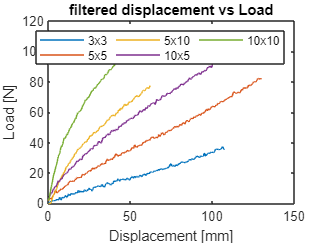


%filtre the signal
window= 10;
load_N_1 = smoothdata(load_N_1,"movmean",window);
load_N_2 = smoothdata(load_N_2,"movmean",window);
load_N_3 = smoothdata(load_N_3,"movmean",window);
load_N_4 = smoothdata(load_N_4,"movmean",window);
load_N_5 = smoothdata(load_N_5,"movmean",window);

plot(pos_mm_1,load_N_1)
hold on

plot(pos_mm_2,load_N_2)
plot(pos_mm_3,load_N_3)
plot(pos_mm_4,load_N_4)
plot(pos_mm_5,load_N_5)
hold off

legend({'3x3','5x5','5x10','10x5','10x10'},...
    'Location','northeast','NumColumns',3)
xlabel("Displacement [mm]")
ylabel("Load [N]")
title("filtered displacement vs Load")

Calculate GreenStrain

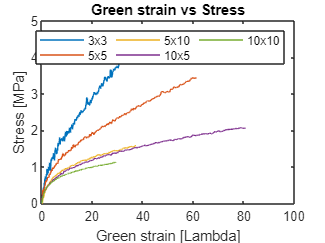

l0_1 = 14.75;
l0_2 = 12.85;
l0_3 = 8.08;
l0_4 = 10.06;
l0_5 = 8.7;


brede_mm_1 = 3.05;
tykkelse_mm_1 = 2.95;
brede_mm_2 = 4.93;
tykkelse_mm_2 = 4.84;
brede_mm_3 = 4.98;
tykkelse_mm_3 = 9.81;
brede_mm_4 = 9.95;
tykkelse_mm_4 = 4.96;
brede_mm_5 = 9.93;
tykkelse_mm_5 = 9.97;


areal_m2_1 = brede_mm_1*tykkelse_mm_1*10^-6;
areal_m2_2 = brede_mm_2*tykkelse_mm_2*10^-6;
areal_m2_3 = brede_mm_3*tykkelse_mm_3*10^-6;
areal_m2_4 = brede_mm_4*tykkelse_mm_4*10^-6;
areal_m2_5 = brede_mm_5*tykkelse_mm_5*10^-6;


stretch_green_1 = ((pos_mm_1+l0_1).^2-l0_1^2)/(2*l0_1^2);
stretch_green_2 = ((pos_mm_2+l0_2).^2-l0_2^2)/(2*l0_2^2);
stretch_green_3 = ((pos_mm_3+l0_3).^2-l0_3^2)/(2*l0_3^2);
stretch_green_4 = ((pos_mm_4+l0_4).^2-l0_4^2)/(2*l0_4^2);
stretch_green_5 = ((pos_mm_5+l0_5).^2-l0_5^2)/(2*l0_5^2);

stress_Pa_1 = load_N_1/areal_m2_1;
stress_Pa_2 = load_N_2/areal_m2_2;
stress_Pa_3 = load_N_3/areal_m2_3;
stress_Pa_4 = load_N_4/areal_m2_4;
stress_Pa_5 = load_N_5/areal_m2_5;

plot(stretch_green_1,stress_Pa_1*10^-6)
hold on
plot(stretch_green_2,stress_Pa_2*10^-6)
plot(stretch_green_3,stress_Pa_3*10^-6)
plot(stretch_green_4,stress_Pa_4*10^-6)
plot(stretch_green_5,stress_Pa_5*10^-6)
hold off

legend({'3x3','5x5','5x10','10x5','10x10'},...
    'Location','northeast','NumColumns',3)
xlabel("Green strain [Lambda]")
ylabel("Stress [MPa]")
title("Green strain vs Stress")

Downsample



down = 20

down = 20

stretch_green_1 = downsample(stretch_green_1+1,down);
stretch_green_2 = downsample(stretch_green_2+1,down);
stretch_green_3 = downsample(stretch_green_3+1,down);
stretch_green_4 = downsample(stretch_green_4+1,down);
stretch_green_5 = downsample(stretch_green_5+1,down);
stress_Pa_1 = downsample(stress_Pa_1,down);
stress_Pa_2 = downsample(stress_Pa_2,down);
stress_Pa_3 = downsample(stress_Pa_3,down);
stress_Pa_4 = downsample(stress_Pa_4,down);
stress_Pa_5 = downsample(stress_Pa_5,down);


d

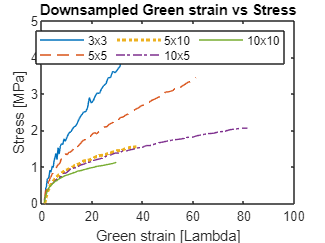



plot(stretch_green_1,stress_Pa_1*10^-6,LineStyle="-")
hold on
plot(stretch_green_2,stress_Pa_2*10^-6,LineStyle="--")
plot(stretch_green_3,stress_Pa_3*10^-6,LineStyle=":",LineWidth=2)
plot(stretch_green_4,stress_Pa_4*10^-6,LineStyle="-.")
plot(stretch_green_5,stress_Pa_5*10^-6,LineStyle="-")
hold off

legend({'3x3','5x5','5x10','10x5','10x10'},...
    'Location','northeast','NumColumns',3)
xlabel("Green strain [Lambda]")
ylabel("Stress [MPa]")
title("Downsampled Green strain vs Stress")

Export

t = table(stretch_green_1,stress_Pa_1,'VariableNames',["stretch_green","stress_filtered"]);
writetable(t,'Data_forComsol/Model_greenstretch_3x3.csv','Delimiter','comma')

t = table(stretch_green_2,stress_Pa_2,'VariableNames',["stretch_green","stress_filtered"]);
writetable(t,'Data_forComsol/Model_greenstretch_5x5.csv','Delimiter','comma')

t = table(stretch_green_3,stress_Pa_3,'VariableNames',["stretch_green","stress_filtered"]);
writetable(t,'Data_forComsol/Model_greenstretch_5x10.csv','Delimiter','comma')

t = table(stretch_green_4,stress_Pa_4,'VariableNames',["stretch_green","stress_filtered"]);
writetable(t,'Data_forComsol/Model_greenstretch_10x5.csv','Delimiter','comma')

t = table(stretch_green_5,stress_Pa_5,'VariableNames',["stretch_green","stress_filtered"]);
writetable(t,'Data_forComsol/Model_greenstretch_10x10.csv','Delimiter','comma')
